# Hierarchical Clustering

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

X = readmatrix("./data/X.csv");
whos X

  Name        Size            Bytes  Class     Attributes

  X         124x4              3968  double              



This code creates a tree of hierarchical clusters.

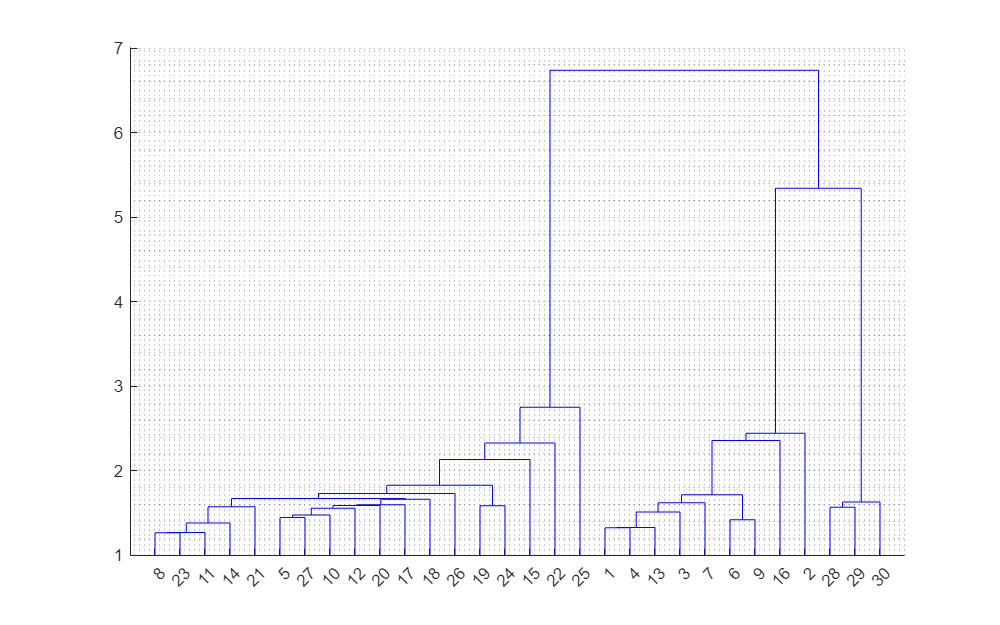

Z = linkage(X);
dendrogram(Z)
grid minor

## Task 1

You can use the `cluster` function to assign observations to one of *k* groups according to the linkage distances `Z`.

`grp` `=` `cluster``(``Z``,``"maxclust"``,``k``)`

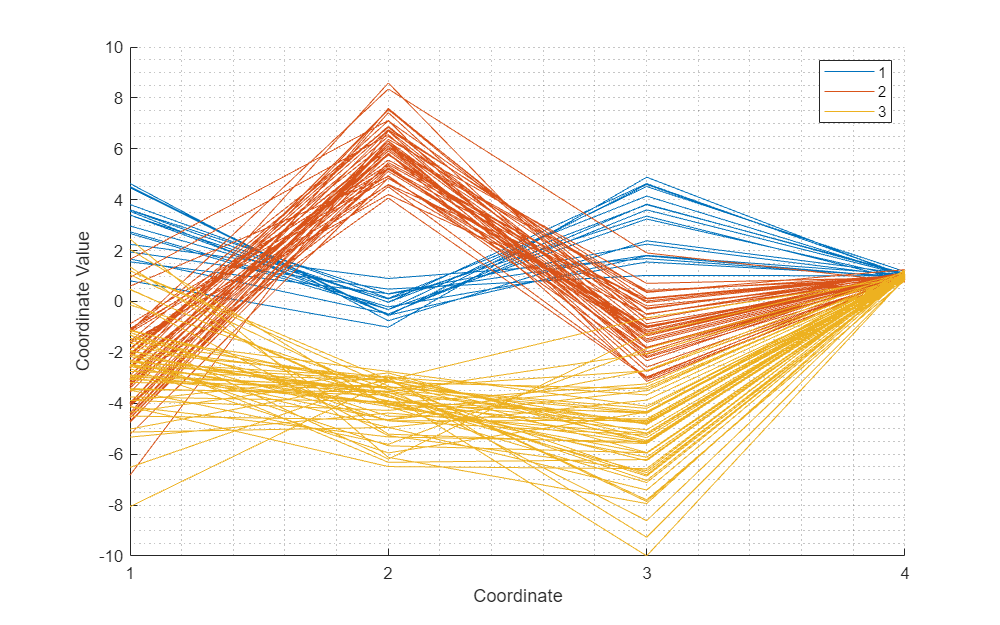

grp = cluster(Z, "maxclust", 3);
parallelcoords(X, "Group", grp)
grid minor

## Task 2

The Cophenetic correlation coefficient quantifies how accurately the tree represents the distances between observations. Values close to 1 indicate a high-quality solution.

You can use `pdist` to compute the pairwise distances of the original data, then use the `cophenet` function to calculate the Cophenetic correleation coefficient.

`ccc` `=` `cophenet``(``linkages``,``distances``)`

Y = pdist(X);
c = cophenet(Z, Y)

c = 0.9302